## Polar Overturning Conceptual Model

#### Live script to run experiments and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20, Sep '20, Oct '23

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory. Crop them to make publication-ready figures.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
more off
% clc
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

## Modern cases based on up-to-date estimates by Tsubouchi et al. (2023).

Exp 1b: Northern hemisphere Fram Strait/Barents Sea Opening with updated parameters from Tsubouchi et al. (2023) in October '23 for Arctic Dynamics workshop. 

To get a plausible solution, the default (Q,F) fluxes from Taka's paper need to be modified (within errors). See figure from Exp3e below and see comments in `define_POC_base_case.mlx`.

model1b = build_POC_model('NH_FSBSO_can_Oct23') ;

 Solutions for experiment: [Exp.~1b Fram Strait+BSO] with file suffices: [NH_FSBSO_can_Oct23]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.7261          |           35.0087          |            3.9000
 Atlantic Water to shelf:             3.7261          |           35.0087          |   0.0249   0.0618   1.7367
 Polar    Water:                     -1.8638          |           34.2596          |  -3.5269  -3.4655  -0.0006
 Overflow Water:             0.1816   1.6089   1.8498 |  34.7951  34.8162  34.9202 |  -3.8799  -0.4909  -0.4309
 Shelf    Water:            -1.8992  -1.9377  -2.2015 |  34.8679  35.5281  40.0000 |  -1.7021  -0.0350  -0.0034
 

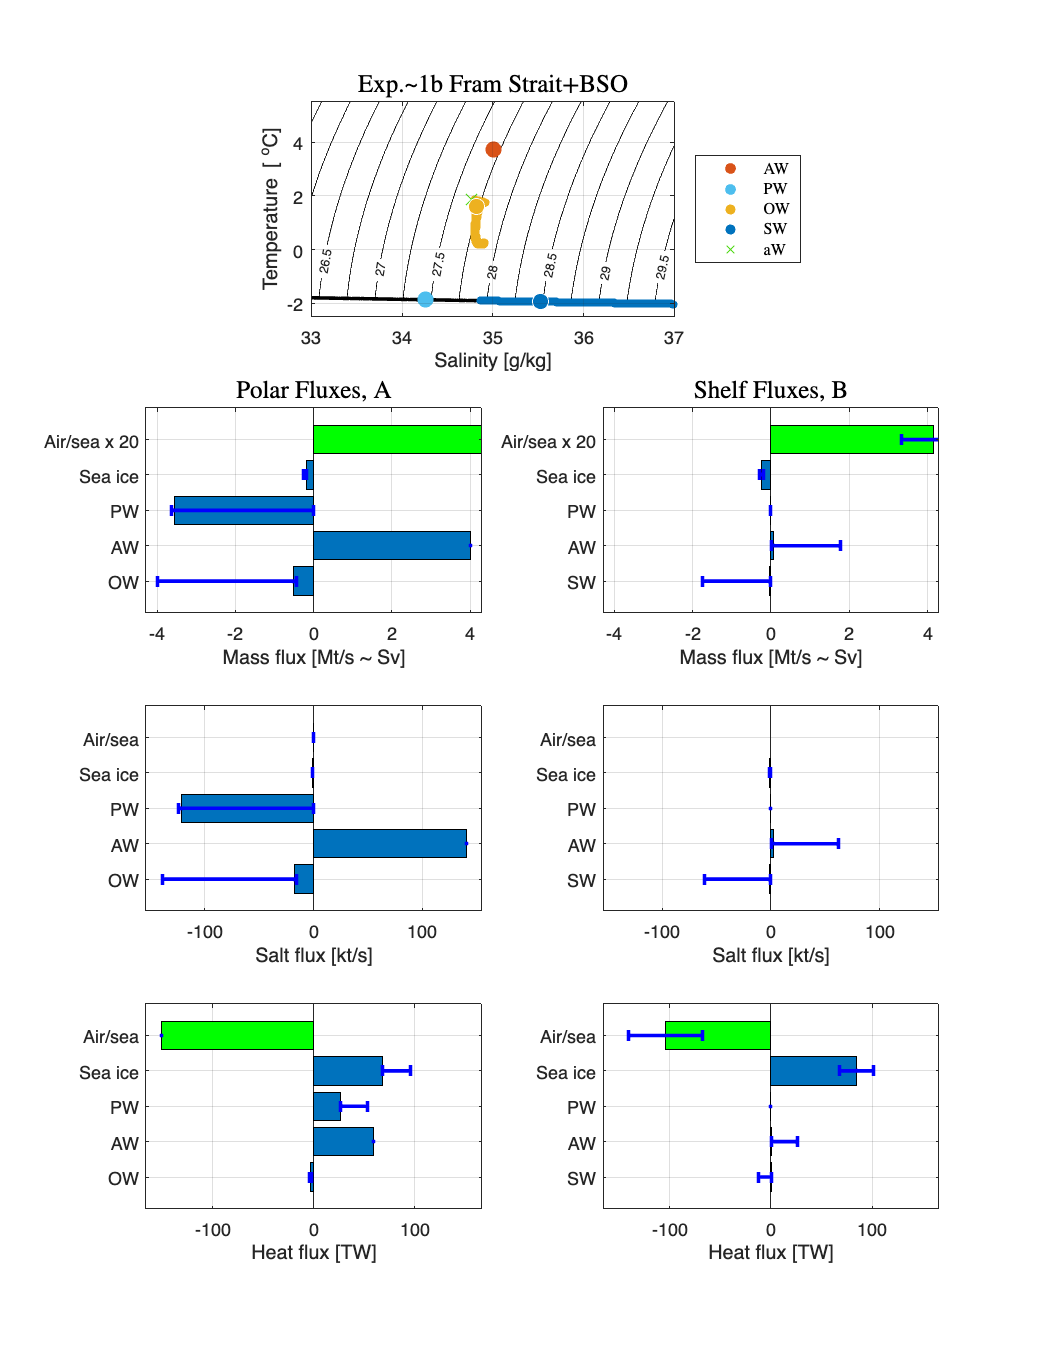

plot_POC_solution(model1b)

Plot the same model solution, but filter possible options based on fit to observed transports and temperature.

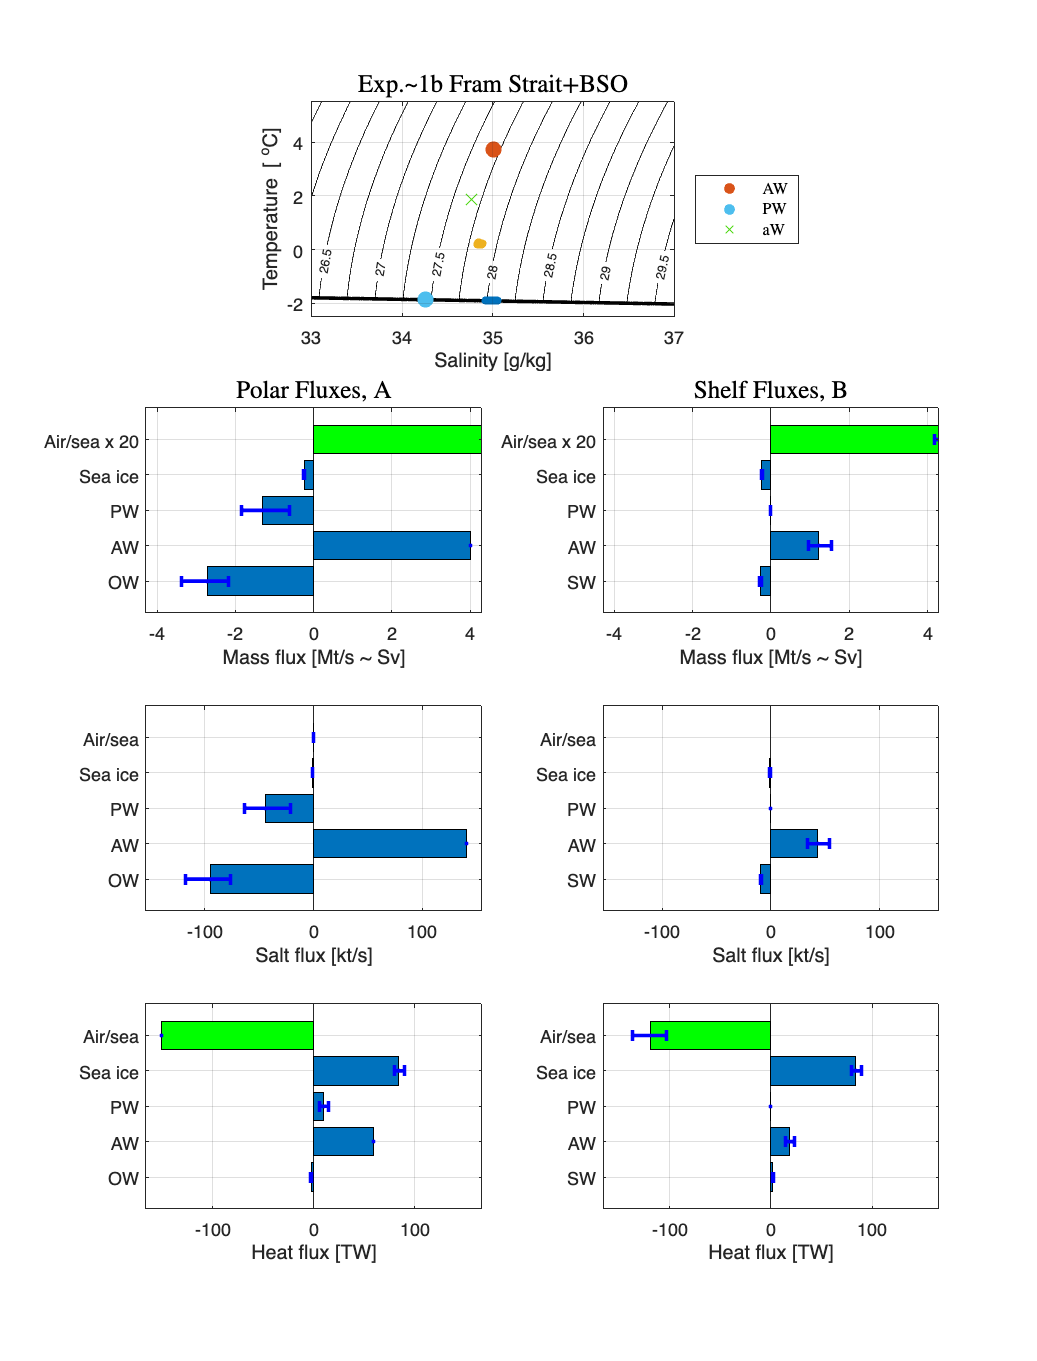

plot_POC_solutionb(model1b)

#### With Exp1b as base case, vary U_1, Q, and F to explore sensitivity:

Exp 3b: Northern hemisphere Fram Strait/Barents Sea Opening with many U_1 values.

model3b = build_POC_model('NH_FSBSO_range_U1') ;

 Solutions for experiment: [Exp.~3b Fram Strait+BSO various $U_1$] with file suffices: [NH_FSBSO_range_U1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   1.3000   4.5500   7.8000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0210   0.6384   2.6011
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.6865  -1.7179  -0.0000
 Overflow Water:            -1.8905   0.8265   1.8498 |  34.5592  34.8605  35.1051 |  -6.3616  -2.8011  -0.0000
 Shelf    Water:            -1.8809  -1.9968  -2.2015 |  34.5539  36.5365  40.0000 |  -2.59

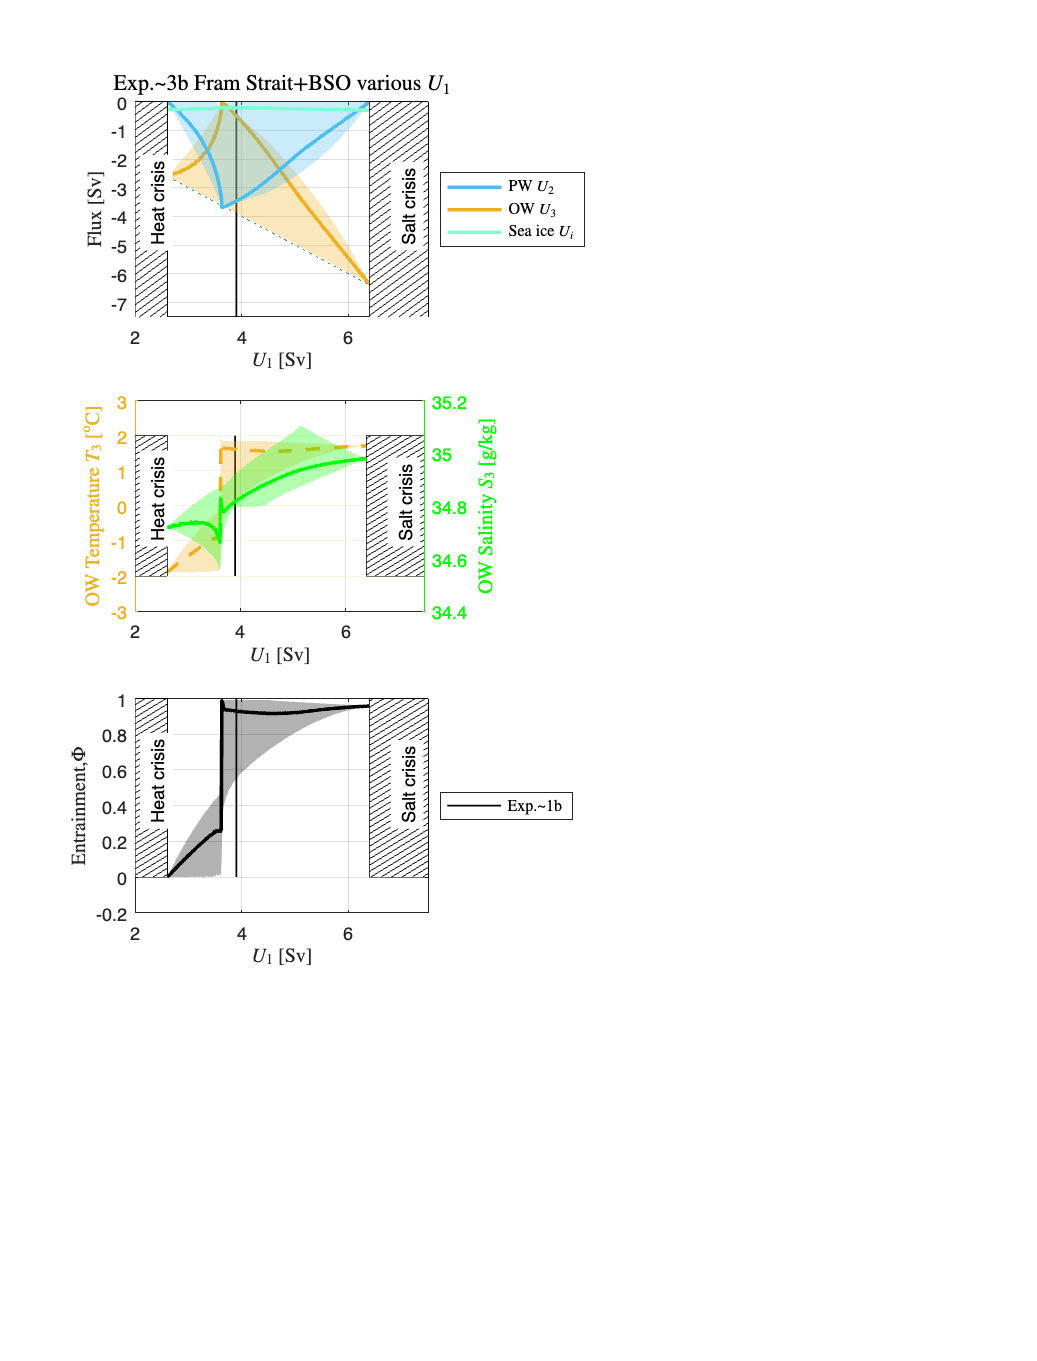

plot_POC_solutions1b(model3b,model1b)

Exp 3c: Northern hemisphere Fram Strait/Barents Sea Opening with many F values.

model3c = build_POC_model('NH_FSBSO_range_F') ;

 Solutions for experiment: [Exp.~3c Fram Strait+BSO various ${\mathcal F}$] with file suffices: [NH_FSBSO_range_F]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   3.9000   3.9000   3.9000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0190   1.2298   3.8863
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9668  -1.5513  -0.0000
 Overflow Water:            -1.8930   0.2398   1.8498 |  34.5539  34.8204  35.0687 |  -3.9056  -2.3697  -0.0000
 Shelf    Water:            -1.8809  -1.9577  -2.2015 |  34.5539  35.8704  40.0000 

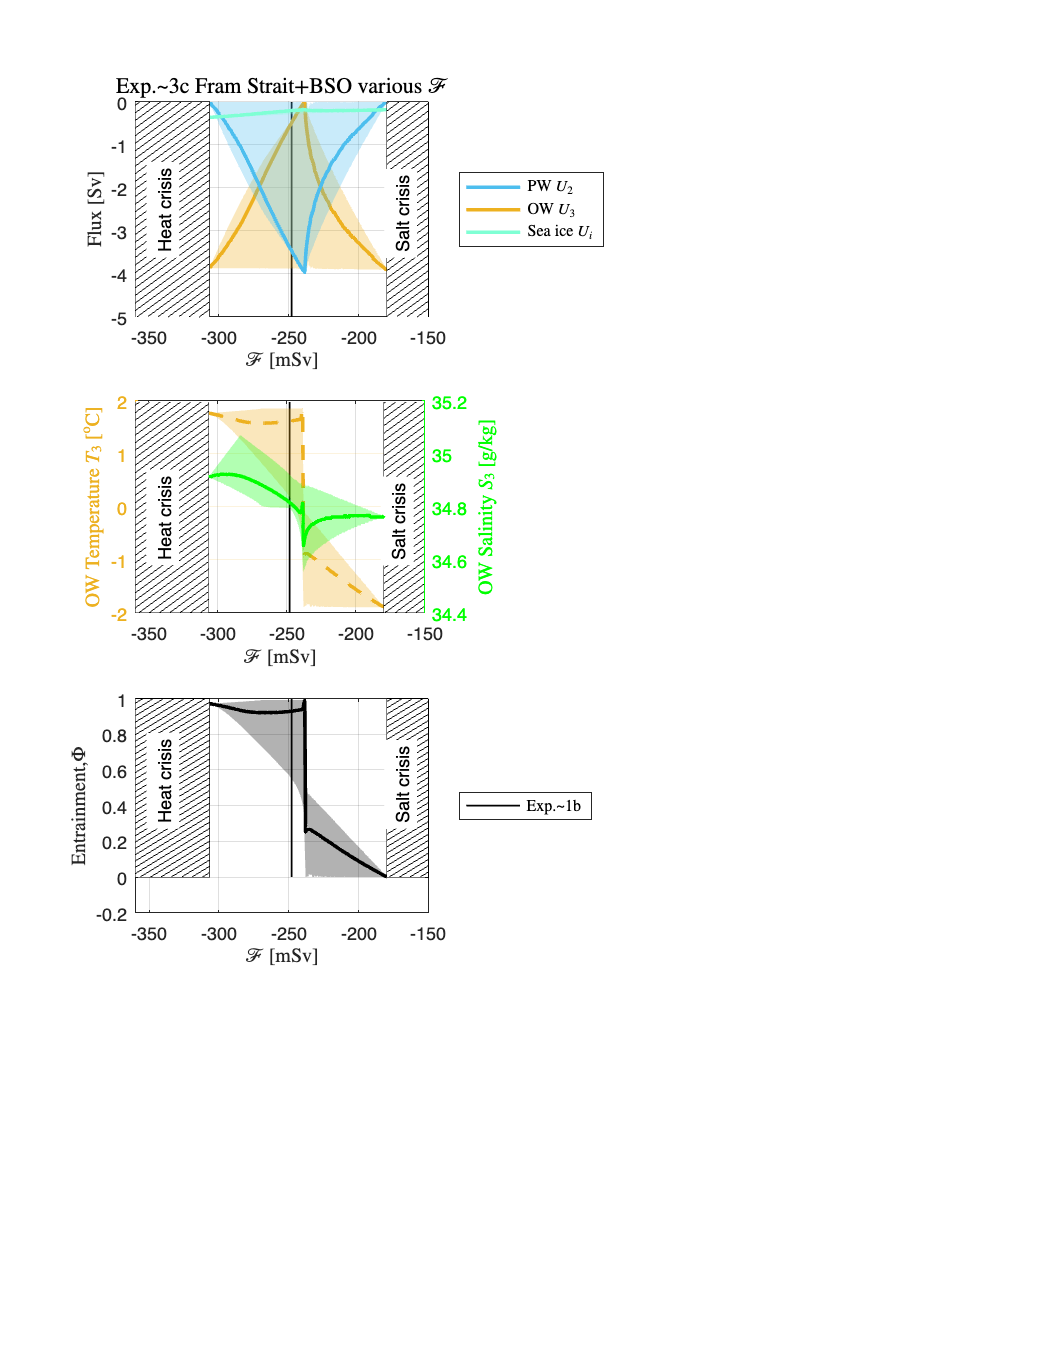

plot_POC_solutions1c(model3c,model1b)

Exp 3d: Northern hemisphere Fram Strait/Barents Sea Opening with many Q values.

model3d = build_POC_model('NH_FSBSO_range_Q') ;

 Solutions for experiment: [Exp.~3d Fram Strait+BSO various ${\mathcal Q}$] with file suffices: [NH_FSBSO_range_Q]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   3.9000   3.9000   3.9000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0204   1.2225   3.8899
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9567  -1.5589  -0.0000
 Overflow Water:            -1.8930   0.2395   1.8498 |  34.5622  34.8200  35.0691 |  -3.8962  -2.3617  -0.0087
 Shelf    Water:            -1.8809  -1.9567  -2.2015 |  34.5539  35.8525  40.0000 

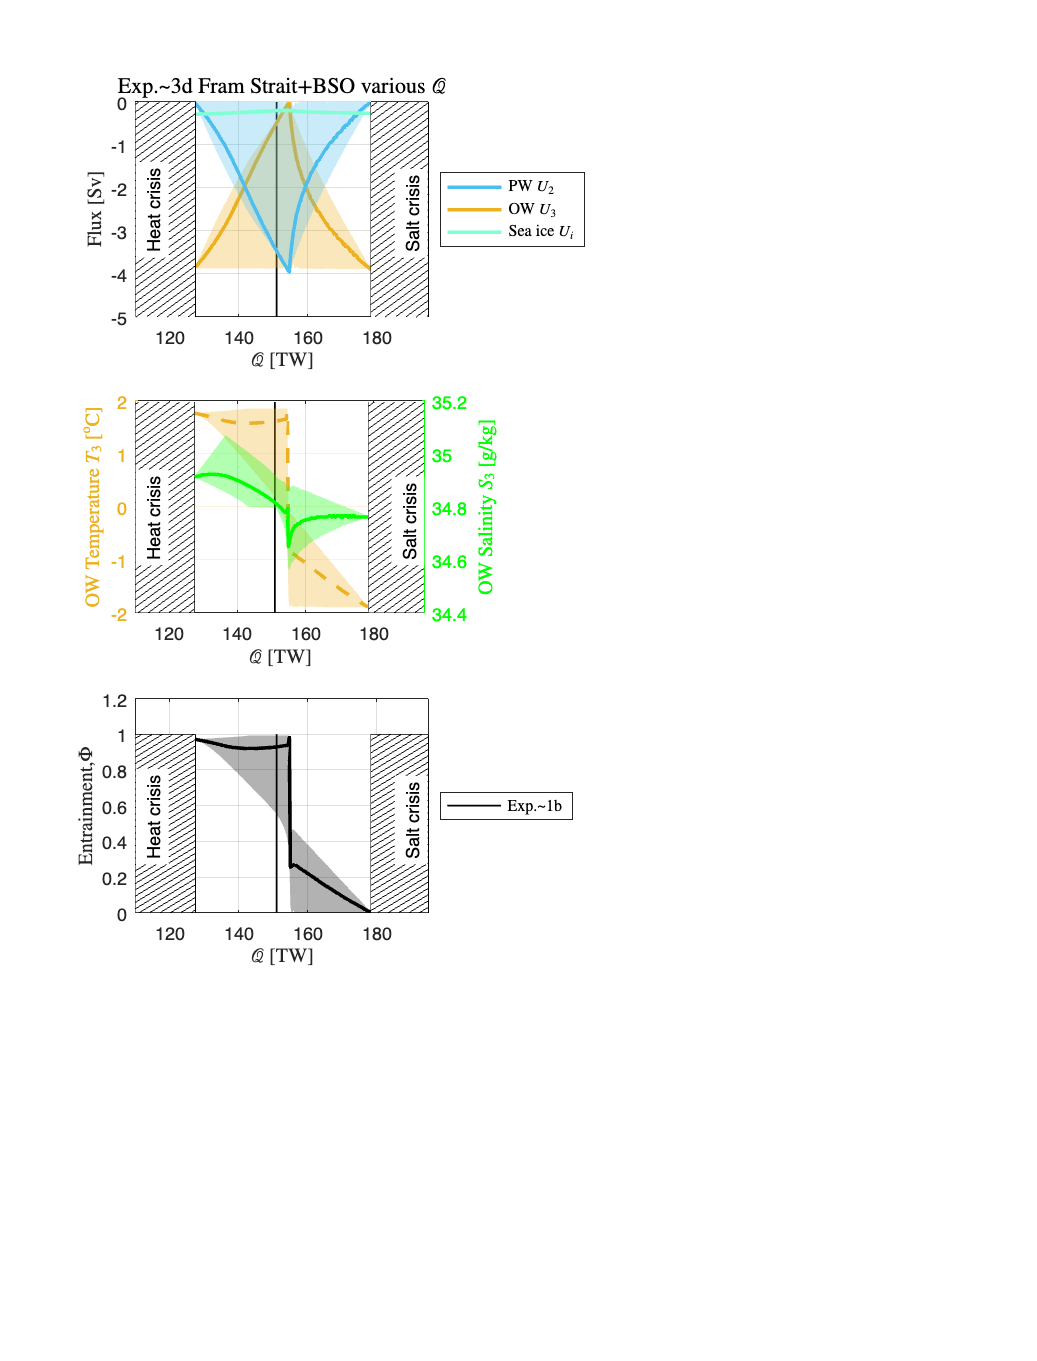

plot_POC_solutions1d(model3d,model1b)

Exp 3e: Northern hemisphere Fram Strait/Barents Sea Opening with many Q, F values, statistically consistent with Tsubouchi et al. (2023) estimates and their error bars. 

Only a subset of these flux pairs give possible POC solutions, and only a subset of those solutions are consistent with transport and temperature observations.

model3e = build_POC_model('NH_FSBSO_can_Oct23_range') ;

 Solutions for experiment: [Exp.~3e Fram Strait+BSO $({\mathcal Q},{\mathcal F})$ range] with file suffices: [NH_FSBSO_can_Oct23_range]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:             3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   3.9000   3.9000   3.9000
 Atlantic Water to shelf:    3.7261   3.7261   3.7261 |  35.0087  35.0087  35.0087 |   0.0159   2.1110   3.8923
 Polar    Water:            -1.8638  -1.8638  -1.8638 |  34.2596  34.2596  34.2596 |  -3.9334  -1.2878  -0.0000
 Overflow Water:            -1.8930  -0.7202   1.8498 |  34.5592  34.7811  35.0653 |  -3.9091  -2.6313  -0.0250
 Shelf    Water:            -1.8809  -1.9138  -2.2015 |  34.55

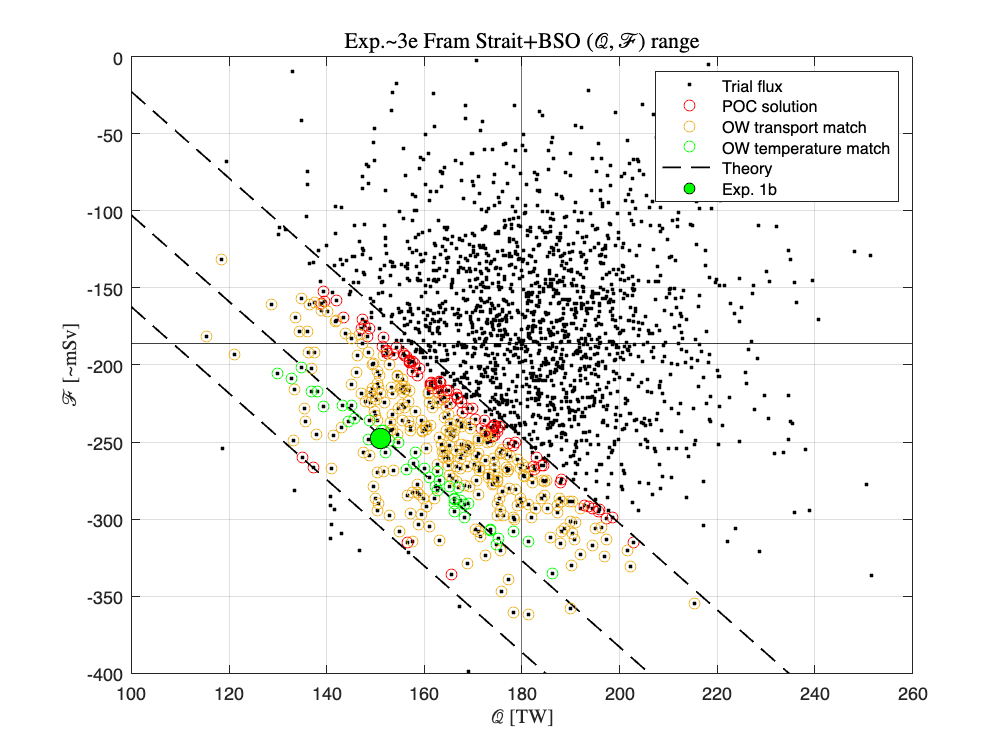

plot_POC_solutions1e(model3e,model1b)

## LGM cases:

Exp G1: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM).

modelG1 = build_POC_model('NH_FSBSO_LGM_can') ;

 Solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   4.4272   4.5250   4.5560
 Polar    Water:                     -1.9481          |           35.7064          |  -0.3128  -0.1229  -0.0100
 Overflow Water:            -1.9693  -1.9174  -1.8613 |  36.0681  36.0739  36.0864 |  -4.7239  -4.6132  -4.4256
 Shelf    Water:            -1.9693  -1.9698  -1.9708 |  36.0689  36.0771  36.0934 |  -4.5392  -4.5095  

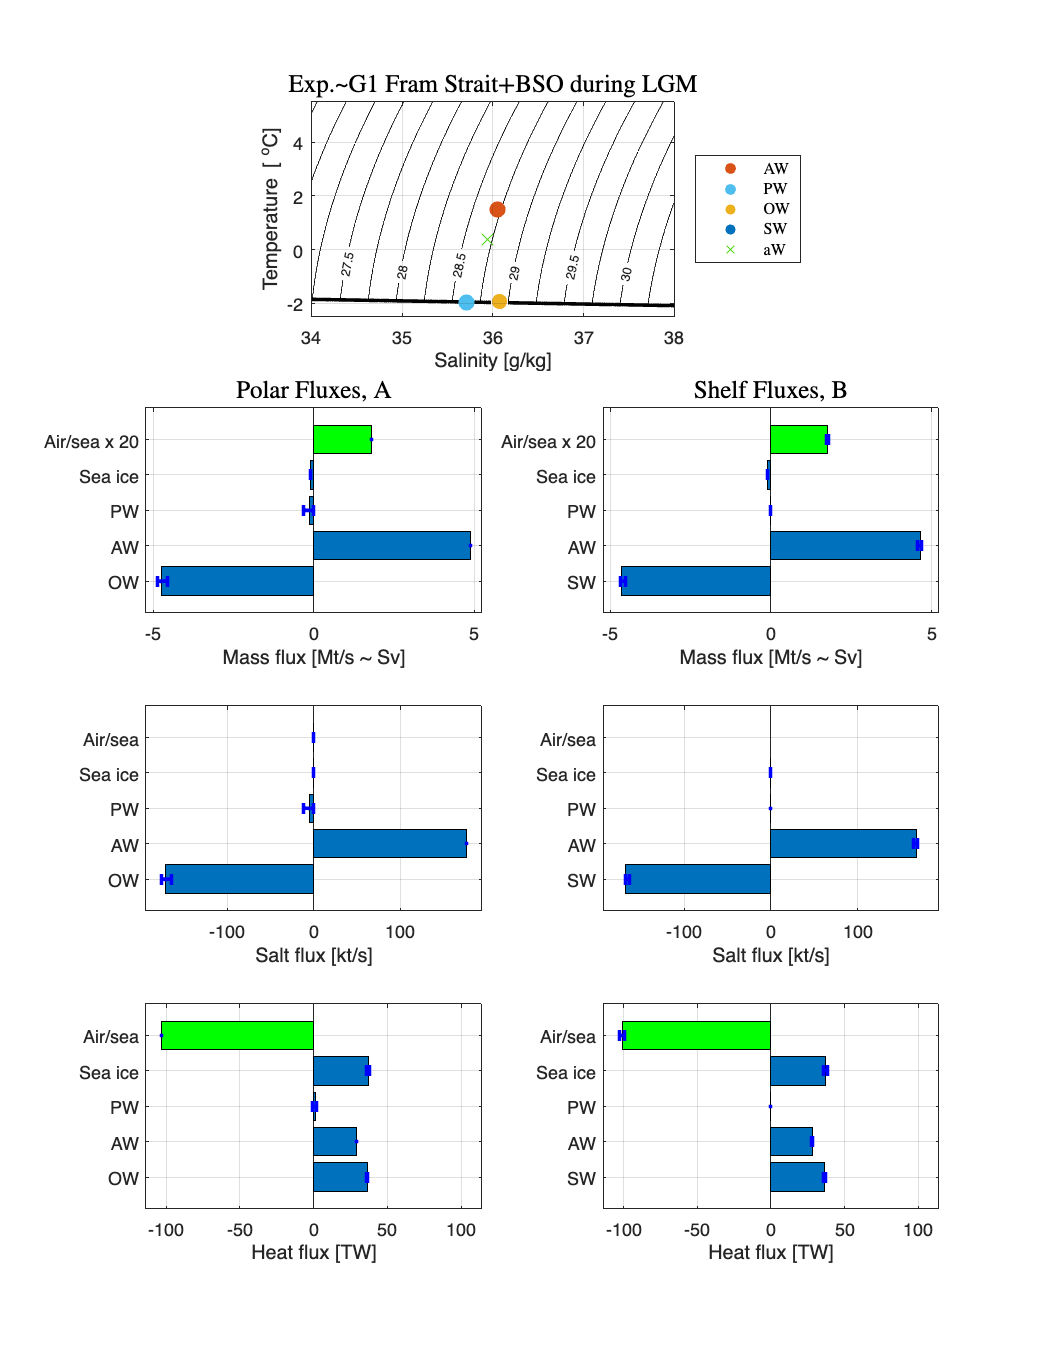

plot_POC_solution(modelG1)

modelG1 = build_stable_isotope_model(modelG1) ;

 Stable isotope solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           2000.15 to  2000.15  |     -0.15 to    -0.15          
 Overflow Water:           1999.34 to  1999.34  |     -0.55 to    -0.55          
 Sea ice:                  1999.32 to  1999.32  |     -0.56 to    -0.56           
 Shelf    Water:           1999.32 to  1999.32  |     -0.56 to    -0.56           



Exp G1b: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with warm AW.

modelG1b = build_POC_model('NH_FSBSO_LGM_hiT1') ;

 Solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      4.0000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             4.0000          |           36.0500          |   0.8089   1.3741   2.2538
 Polar    Water:                     -1.9189          |           35.2049          |  -3.2392  -2.0747  -0.0101
 Overflow Water:            -0.0265   0.0374   0.1891 |  35.7822  35.8431  35.9223 |  -4.7471  -2.7369  -1.5988
 Shelf    Water:            -1.9532  -1.9603  -1.9711 |  35.7925  35.9147  36.0980 |  -2.

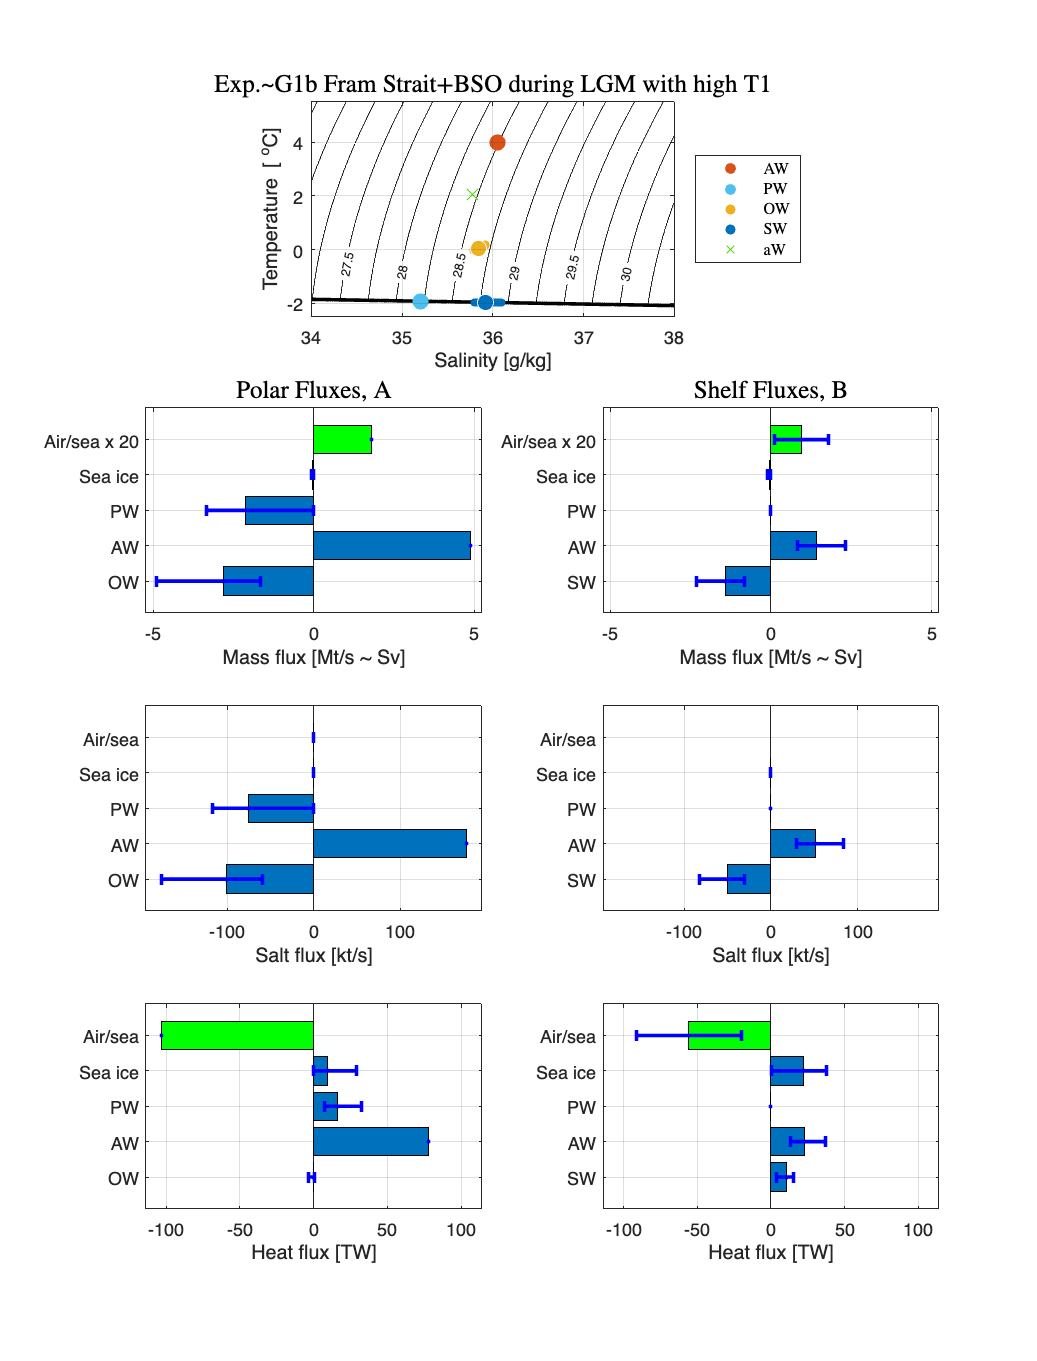

plot_POC_solution(modelG1b)

modelG1b = build_stable_isotope_model(modelG1b) ;

 Stable isotope solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           1999.71 to  1999.71  |     -0.37 to    -0.37          
 Overflow Water:           1999.11 to  1999.11  |     -0.67 to    -0.67          
 Sea ice:                  1998.02 to  1998.02  |     -1.21 to    -1.21           
 Shelf    Water:           1998.02 to  1998.02  |     -1.21 to    -1.21           



Exp G2: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with lower Q

modelG2 = build_POC_model('NH_FSBSO_LGM_lowQ') ;

 Solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   2.1685   2.6530   3.1441
 Polar    Water:                     -1.9481          |           35.7064          |  -2.6066  -1.4686  -0.0094
 Overflow Water:            -1.9648  -1.5120  -1.1528 |  35.9907  36.0560  36.1283 |  -4.7172  -3.2852  -2.1643
 Shelf    Water:            -1.9648  -1.9703  -1.9789 |  35.9913  36.0852  36.2323 |  -3.116

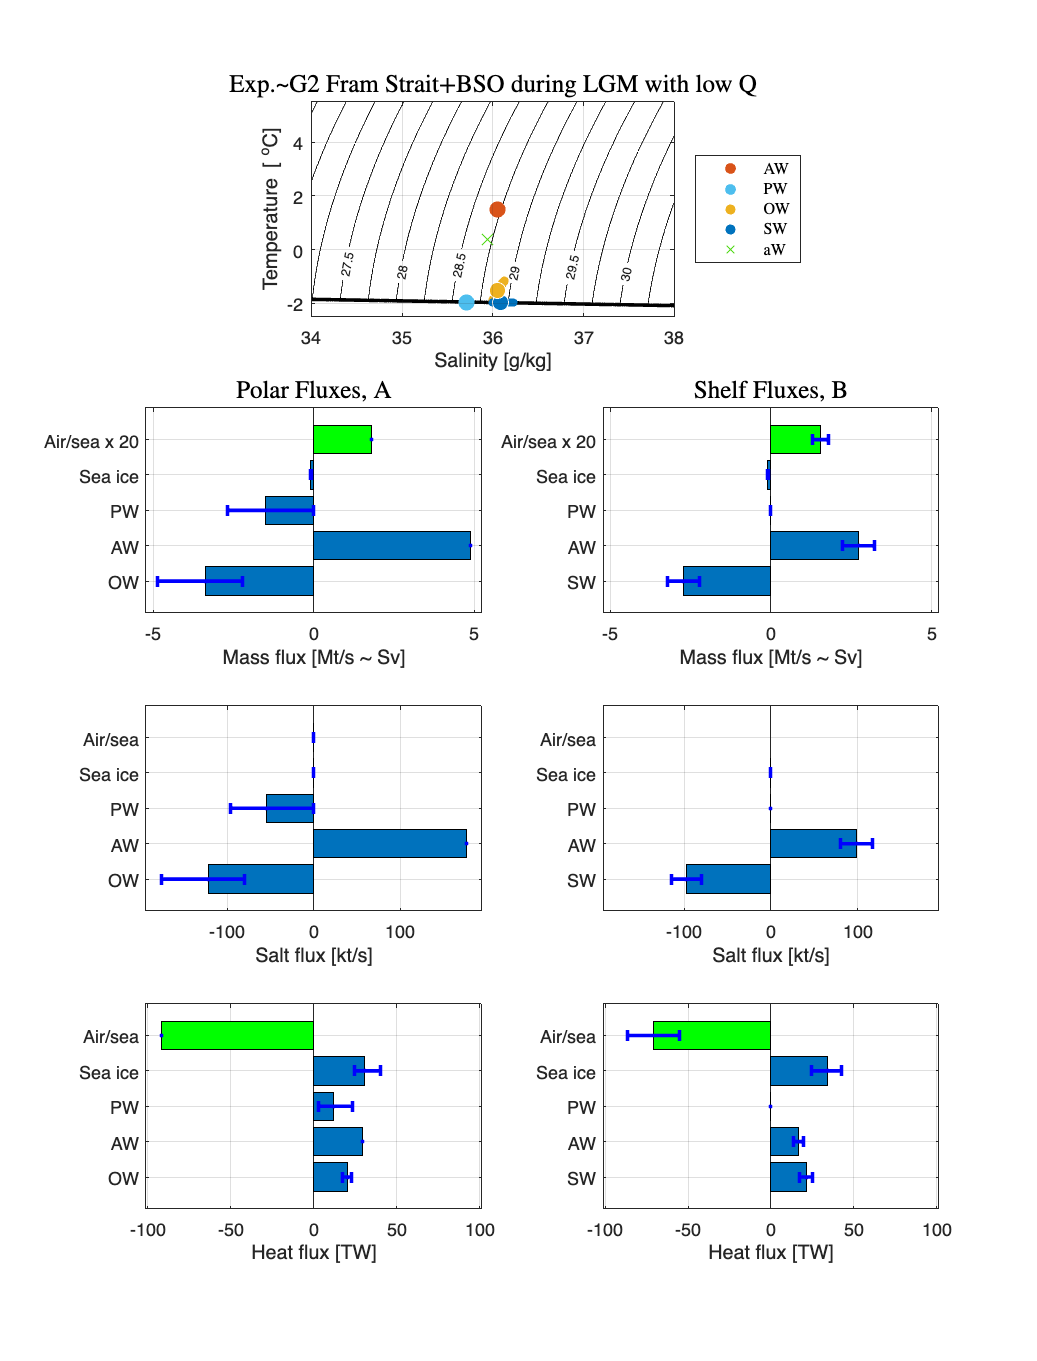

plot_POC_solution(modelG2)

modelG2 = build_stable_isotope_model(modelG2) ;

 Stable isotope solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           2000.15 to  2000.15  |     -0.15 to    -0.15          
 Overflow Water:           1999.02 to  1999.02  |     -0.71 to    -0.71          
 Sea ice:                  1998.70 to  1998.70  |     -0.87 to    -0.87           
 Shelf    Water:           1998.70 to  1998.70  |     -0.87 to    -0.87           

